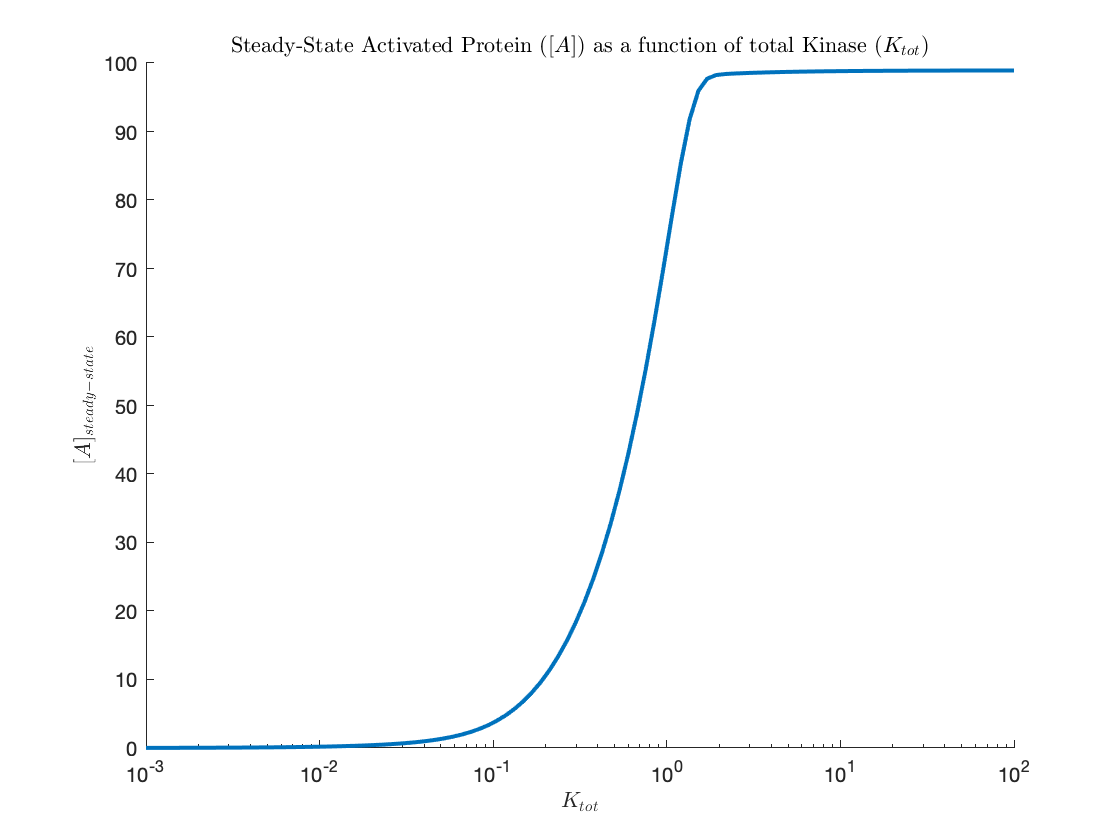

clear all

%rate constants, all units s^-1 except for kAon and kIon are s^-1 uM^-1
kAon = 10;
kAoff = 10;
kIon = 10;
kIoff = 10;
kIcat = 10;
kAcat = 100;

%kinase and phosphatase
Ptot = 1;

n = 100;
sweep = logspace(-3,2,n);
Asteady = zeros(1,100);

for i=1:n
    Ktot = sweep(i);
    dAdt =@(A,AP,I,IK) -kAon*(Ptot - AP)*A + kAoff*AP + kAcat*IK;
    dAPdt =@(A,AP,I,IK) kAon*(Ptot - AP)*A - kAoff*AP - kIcat*AP;
    dIdt =@(A,AP,I,IK) -kIon*(Ktot - IK)*I + kIoff*IK + kIcat*AP;
    dIKdt =@(A,AP,I,IK) kIon*(Ktot - IK)*I - kIoff*IK - kAcat*IK;

    [T, X] = ode45(@(t,x)[dAdt(x(1),x(2),x(3),x(4));dAPdt(x(1),x(2),x(3),x(4));...
    dIdt(x(1),x(2),x(3),x(4));dIKdt(x(1),x(2),x(3),x(4))],[0,1],[0.0,0.0,100.0,0.0]);

    Asteady(i) = X(end,1);
end

figure; hold on;
plot(sweep,Asteady,'LineWidth',2)
set(gca, 'XScale', 'log')
xlabel('$K_{tot}$',"Interpreter","latex")
ylabel('$[A]_{steady-state}$','Interpreter',"latex")
title('Steady-State Activated Protein ($[A]$) as a function of total Kinase ($K_{tot}$)','Interpreter',"latex")